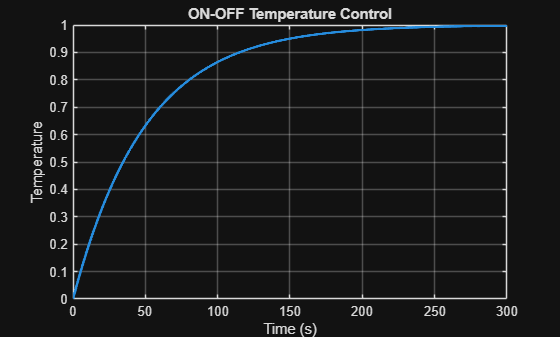

clc;
clear;
close all;

%% Oven Model (First Order Thermal System)
K = 1;          % System gain
tau = 50;       % Time constant

num = K;
den = [tau 1];

G = tf(num,den);   % Transfer function of oven

t = 0:0.1:300;     % Simulation time
setpoint = 1;      % Desired temperature (normalized)

%% ON-OFF Controller Simulation
y = zeros(size(t));
u = zeros(size(t));

for k = 2:length(t)

    if y(k-1) < setpoint
        u(k) = 1;
    else
        u(k) = 0;
    end
    
    % System response (simple discrete approximation)
    y(k) = y(k-1) + (0.1/tau)*(-y(k-1) + K*u(k));
end

figure;
plot(t,y,'LineWidth',2);
title('ON-OFF Temperature Control');
xlabel('Time (s)');
ylabel('Temperature');
grid on;

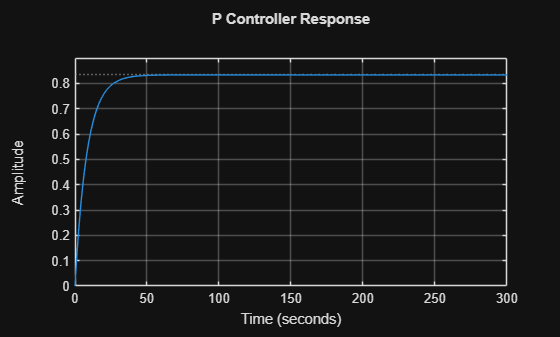


%% P Controller
Kp = 5;
C_P = pid(Kp);

T_P = feedback(C_P*G,1);

figure;
step(T_P,t);
title('P Controller Response');
grid on;

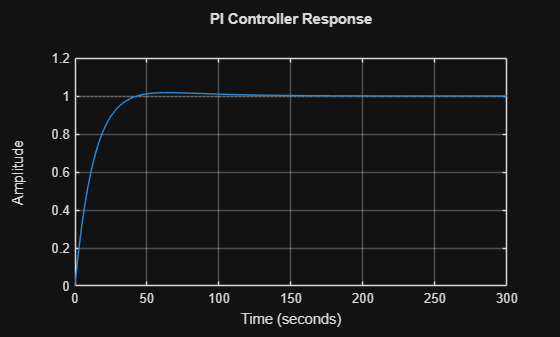


%% PI Controller
Kp = 4;
Ki = 0.1;

C_PI = pid(Kp,Ki);

T_PI = feedback(C_PI*G,1);

figure;
step(T_PI,t);
title('PI Controller Response');
grid on;

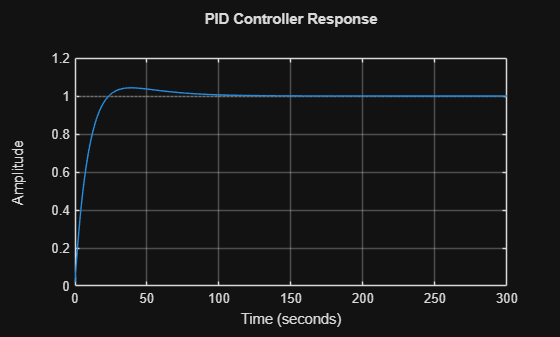


%% PID Controller
Kp = 6;
Ki = 0.2;
Kd = 1;

C_PID = pid(Kp,Ki,Kd);

T_PID = feedback(C_PID*G,1);

figure;
step(T_PID,t);
title('PID Controller Response');
grid on;

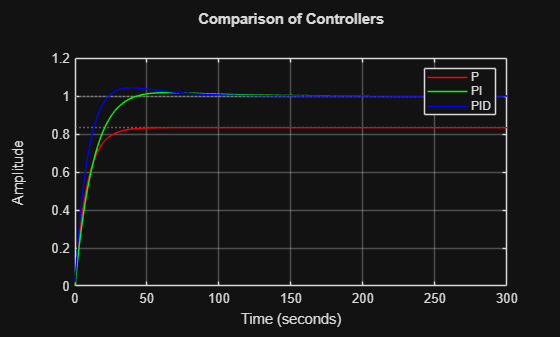


%% Comparison Plot
figure;
step(T_P,'r',T_PI,'g',T_PID,'b',t);
legend('P','PI','PID');
title('Comparison of Controllers');
grid on;

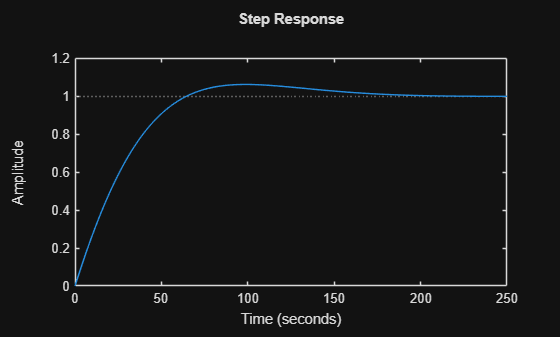

C = pidtune(G,'PID');
T = feedback(C*G,1);
step(T)